% m_\phi^2 vs. R_0, varying \alpha, keeping \beta = 0.20

% Parameters
R_c = 1;  % Given in the problem
beta = 0.20;  % Keep beta fixed at 0.20
alpha_vals = [0.10, 0.15, 0.20];  % Vary alpha values
R_0_range = linspace(0.01, 3, 100);  % Range of R_0 to plot (0 to 3)

% Pre-allocate array for m_phi squared results
m_phi_squared_alpha = zeros(length(alpha_vals), length(R_0_range));

% Calculate m_\phi^2 for different alpha values
for i = 1:length(alpha_vals)
    alpha = alpha_vals(i);
    % Calculate m_\phi^2 based on the given formula
    m_phi_squared_alpha(i, :) = (R_c .* exp(R_0_range / R_c) .* ...
        (pi * (R_0_range.^4 + R_c^4).^2 - 8 * alpha * R_0_range.^5 * R_c^3) - ...
        pi * beta * (R_0_range + R_c) .* (R_0_range.^4 + R_c^4).^2) ./ ...
        (3 * pi * beta * (R_0_range.^4 + R_c^4).^2 - 6 * alpha * R_c^4 .* exp(R_0_range / R_c) .* (R_c^4 - 3 * R_0_range.^4));
end

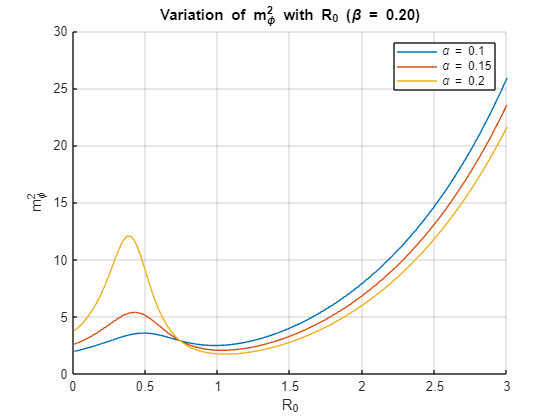

% Plot the first graph
figure;
hold on;
for i = 1:length(alpha_vals)
    plot(R_0_range, m_phi_squared_alpha(i, :), 'DisplayName', ['\alpha = ', num2str(alpha_vals(i))]);
end
xlabel('R_0');
ylabel('m_\phi^2');
title('Variation of m_\phi^2 with R_0 (\beta = 0.20)');
legend('show');
grid on;
axis([0 3 0 30]); % Set the x and y axis limits
hold off;